# Secular determinant demo

Demonstrate QGLAB's secular determinant calculation on a lollipop graph with a Kirchoff boundary condition at the pendant vertex and a Kirchhoff-Robin boundary condition at the interior vertex.

First we set up graphs with both discretizations.

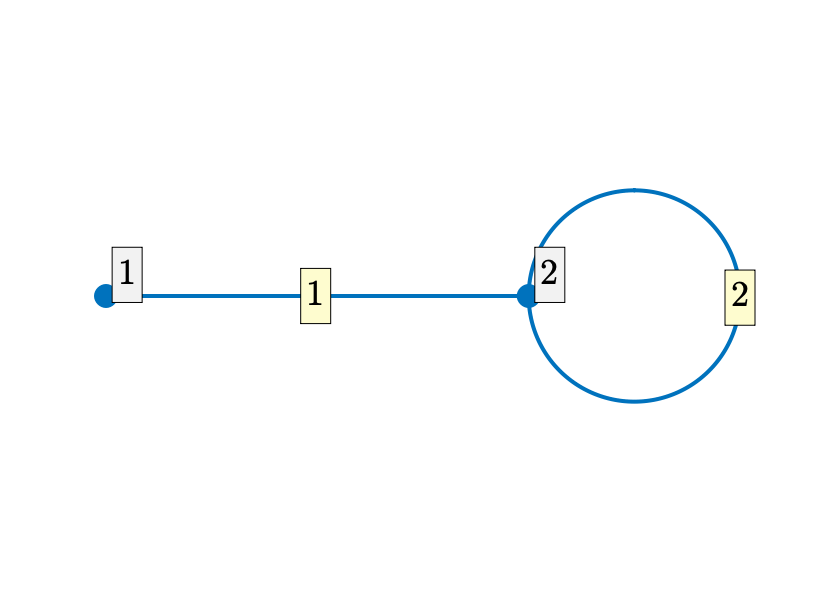

robinCoeff=[0,1];
Phi = quantumGraphFromTemplate('multibell','nBells',1,'robinCoeff',robinCoeff,'discretization','Chebyshev','nx',16);
PhiU = quantumGraphFromTemplate('multibell','nBells',1,'robinCoeff',robinCoeff,'discretization','Uniform','nx',64);
PhiU.plot('layout')

Now we calculate its secular determinant, and find all its zeros on the interval (0,5)

SD=Phi.secularDet

$$SD = \frac{2\,x\,\cos\left(2\,x\right)+\cos\left(2\,x\right)\,\sin\left(\pi \,x\right)-2\,x\,\cos\left(2\,x\right)\,\cos\left(\pi \,x\right)+x\,\sin\left(2\,x\right)\,\sin\left(\pi \,x\right)}{\sqrt{9\,x^{2}+1}}$$

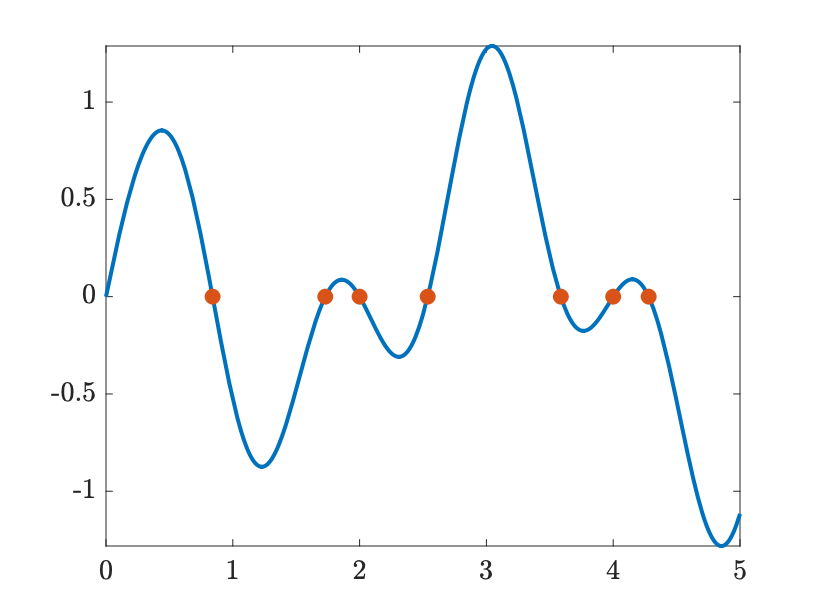

kmax= 5;
kstar=allZeros(SD,[0 kmax]);
fplot(SD,[0 kmax])
hold on;
plot(kstar,zeros(size(kstar)),'o','color',mcolor(2),'MarkerFaceColor',mcolor(2));

This is the secular determinant we calculated by hand, using pencil and paper. It doesn't exactly match what we showed above because the normalizations conditions used in the `secularDet` method are different than in our hand calculation. What matters is that the roots match up exactly.


$$\Sigma(k)=-8 k^2 \cos (2 k)+2 k^2 \cos (2 k-\pi  k)+6 k^2 \cos (\pi  k+2 k)+2 k \sin (2 k-\pi  k)-2 k \sin (\pi  k+2 k)$$


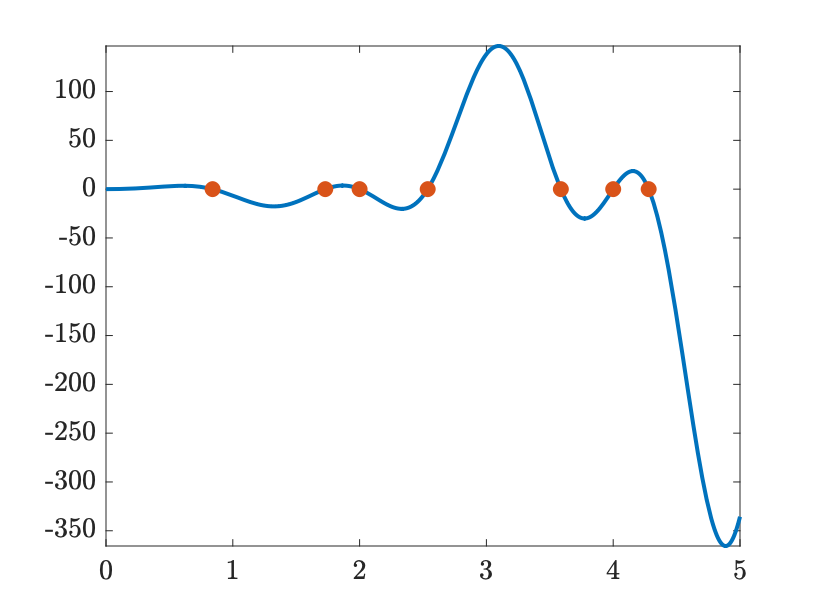

SDexact=@(k) -(-8*k.^2.*cos(2*k) + 2*k.^2.*cos(2*k - k*pi) + ... 
              6*k.^2.*cos(2*k + k*pi) + 2*k.*sin(2*k - k*pi) - ...
              2*k.*sin(2*k + k*pi));
clf;
fplot(SDexact,[0 kmax])
hold on;
plot(kstar,zeros(size(kstar)),'o','color',mcolor(2),'MarkerFaceColor',mcolor(2));

Now we calculate the eigenvalues, using both the uniform and Chebyshev discretizations. We throw out the positive roots, and plot $\sqrt{-\lambda_i}$, since $\lambda_i = -k_i^2$, where $k_i$ are the roots of the secular determinant. All lie right on top of each otehr. 

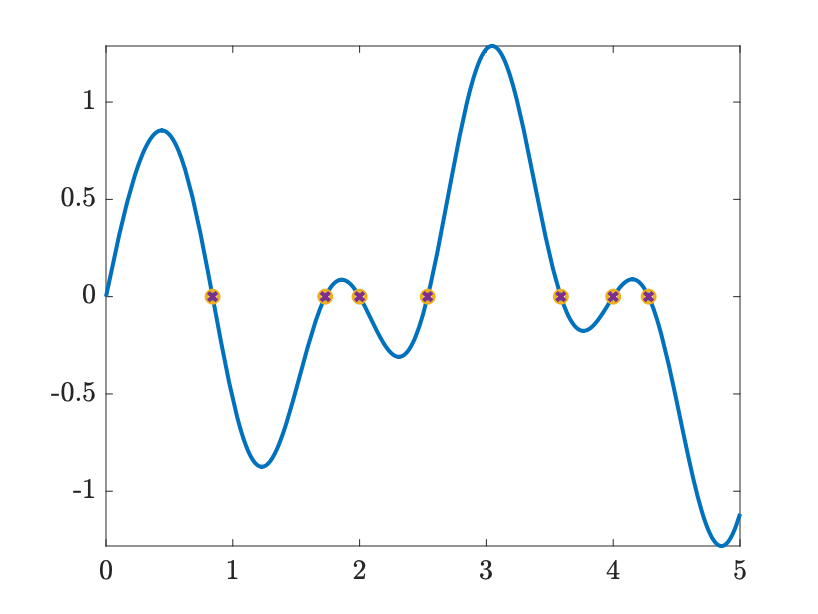

[~,d1]=Phi.eigs(8); d1 = d1(d1<=0);
[~,d2]=PhiU.eigs(8); d2 = d2(d2<=0);
clf;
fplot(SD,[0 kmax])
hold on;
plot(sqrt(-d1),zeros(size(d1)),'o','color',mcolor(3))
plot(sqrt(-d2),zeros(size(d2)),'x','color',mcolor(4))